clear
addpath(genpath(pwd));

opts = spreadsheetImportOptions("NumVariables", 11);

% Specify sheet and range
opts.Sheet = "InflowData";
opts.DataRange = "A2:K13680";

% Specify column names and types
opts.VariableNames = ["DatetimeCETCESTDDMMYYYYHHmm", "DMAALs", "DMABLs", "DMACLs", "DMADLs", "DMAELs", "DMAFLs", "DMAGLs", "DMAHLs", "DMAILs", "DMAJLs"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
InflowData1 = readtable("InflowData_1.xlsx", opts, "UseExcel", false)

InflowData1 = 13679×11 table
    DatetimeCETCESTDDMMYYYYHHmm    DMAALs    DMABLs    DMACLs    DMADLs    DMAELs    DMAFLs    DMAGLs    DMAHLs    DMAILs    DMAJLs
    ___________________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

       01-Jan-2021 00:00:00         NaN       NaN         3.7     NaN       NaN       NaN       NaN       NaN       NaN       NaN  
       01-Jan-2021 01:00:00         NaN       NaN      3.5625     NaN       NaN       NaN       NaN       NaN       NaN       NaN  
       01-Jan-2021 02:00:00         NaN       NaN      3.2725     Na


opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "WeatherData";
opts.DataRange = "A2:E13848";

% Specify column names and types
opts.VariableNames = ["DatetimeCETCESTDDMMYYYYHHmm", "RainfallDepthmm", "AirTemperatureC", "AirHumidity", "Windspeedkmh"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double"];

% Import the data
WeatherData1 = readtable("WeatherData_1.xlsx", opts, "UseExcel", false)

WeatherData1 = 13847×5 table
    DatetimeCETCESTDDMMYYYYHHmm    RainfallDepthmm    AirTemperatureC    AirHumidity    Windspeedkmh
    ___________________________    _______________    _______________    ___________    ____________

       01-Jan-2021 00:00:00                0                7.2              79               9     
       01-Jan-2021 01:00:00                0                7.3              79               6     
       01-Jan-2021 02:00:00                0                7.6              78               4     
       01-Jan-2021 03:00:00                0                8.2              75               4     
       01-Jan-2021 04:00:00                0                7.7              77               7     
       01-Jan-2021 05:00:00              0.1                7.5              81              

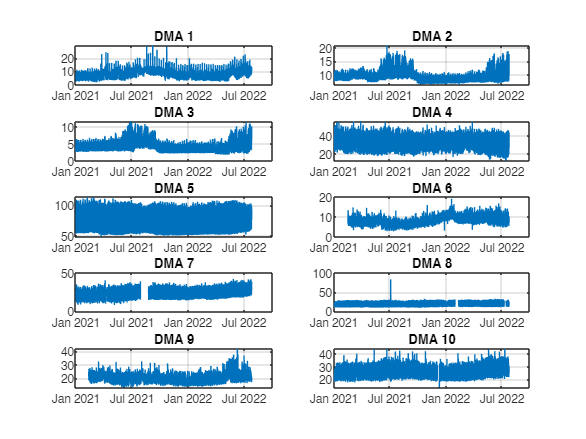




TQ = InflowData1.DatetimeCETCESTDDMMYYYYHHmm;
Q = table2array(InflowData1(:,2:11));
LogQ = log(Q);
Tweather = WeatherData1.DatetimeCETCESTDDMMYYYYHHmm;
W = table2array(WeatherData1(:,2:5));
Tw = Tweather(1:length(Q));
Rain = W(:,1);
AirT = W(:,2);
AirH = W(:,3);
Wind = W(:,4);


P = [162, 531, 607, 2094 , 7955, 1135, 3180, 2901, 425, 776]; % Population

dt = datetime(TQ, 'InputFormat', 'dd-MMM-yyyy HH:mm:ss');
figure;
for i = 1:10
    subplot(5,2,i);
    plot(TQ, Q(:,i));  
    title(['DMA ' num2str(i)]);
    grid on
end

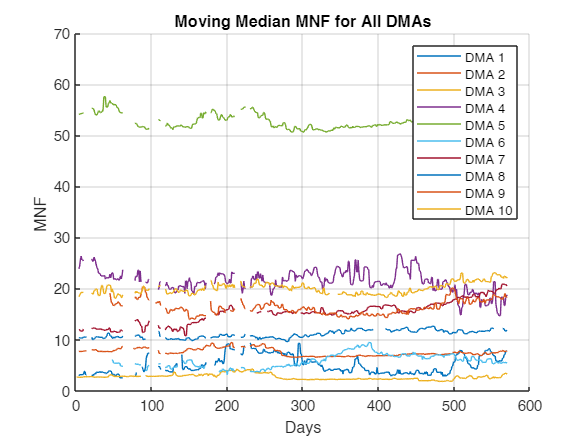

% Define night hours (example: 00:00 - 04:00)
nightStartHour = 0; % 00:00
nightEndHour = 6; % 04:00

% Number of days in the dataset
numDays = floor(days(TQ(end) - TQ(1))) + 1;

% Preallocate the MNF matrix (rows: days, columns: DMAs)
dailyMNF = zeros(numDays, size(Q, 2));

% Compute daily MNF
for dayIdx = 1:numDays
    % Define night period for the current day
    nightStart = dateshift(TQ(1) + days(dayIdx - 1), 'start', 'day') + hours(nightStartHour);
    nightEnd = dateshift(TQ(1) + days(dayIdx - 1), 'start', 'day') + hours(nightEndHour);

    % Find indices for the current night
    nightIndices = TQ >= nightStart & TQ < nightEnd;

    % Calculate MNF for each DMA
    dailyMNF(dayIdx, :) = nanmin(Q(nightIndices, :), [], 1); % Min along the first dimension
end

% Apply a moving median filter (window size = 5 days)
windowSize = 5;
movingMedianMNF = zeros(size(dailyMNF));

for dmaIdx = 1:size(Q, 2)
    movingMedianMNF(:, dmaIdx) = movmedian(dailyMNF(:, dmaIdx), windowSize);
end

% movingMedianMNF is the matrix with the moving median of MNF for each DMA

% Plot the moving median MNF for all DMAs
figure;
hold on;

% Assuming each column in movingMedianMNF represents a DMA
for dmaIdx = 1:size(movingMedianMNF, 2)
    plot(movingMedianMNF(:, dmaIdx), 'DisplayName', ['DMA ' num2str(dmaIdx)]);
end

hold off;

% Enhancing the plot
title('Moving Median MNF for All DMAs');
xlabel('Days');
ylabel('MNF ');
legend('show'); % Show a legend identifying each DMA
grid on; % Add a grid for better readability

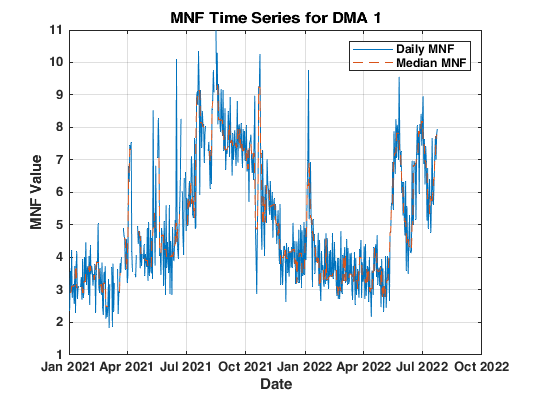

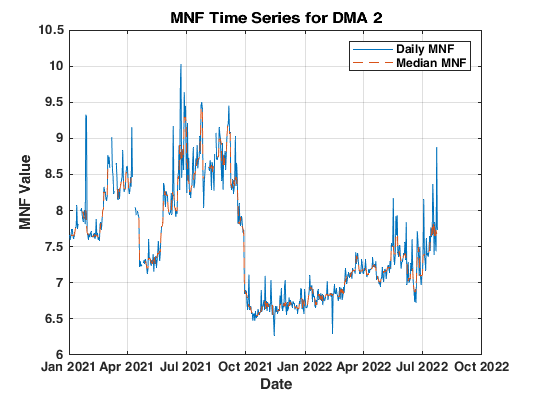

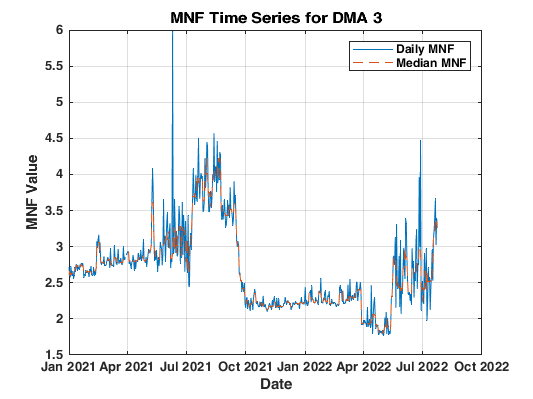

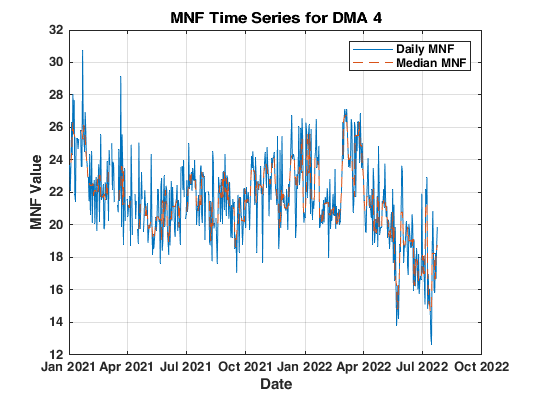

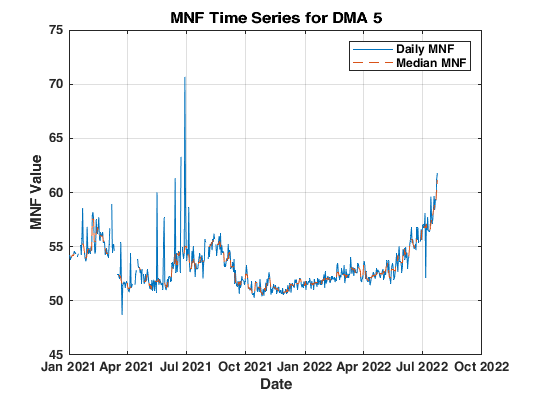

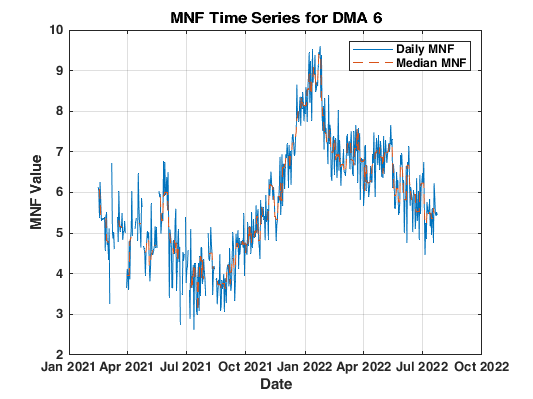

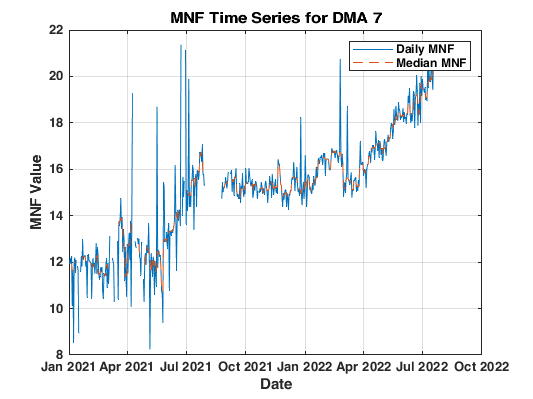

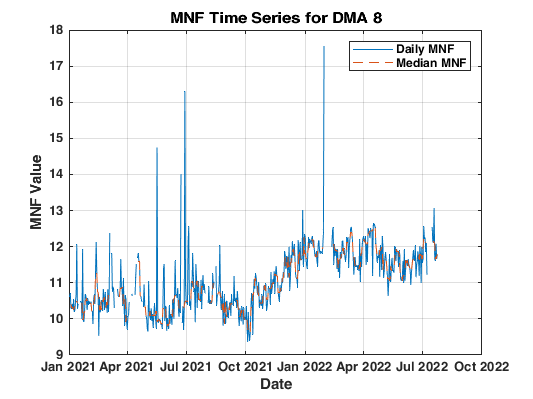

% Extract unique dates from the TQ datetime array
uniqueDates = unique(dateshift(TQ, 'start', 'day'));

% Check if the number of unique dates matches the number of rows in dailyMNF
if length(uniqueDates) ~= size(dailyMNF, 1)
    error('Mismatch between dates and MNF data rows');
end

% Now, simply use dailyMNF as your time series matrix
timeSeriesMNFMatrix = dailyMNF;

% Plotting MNF and Median MNF for each DMA
for dmaIndex = 1:size(dailyMNF, 2)
    figure;
    plot(uniqueDates, timeSeriesMNFMatrix(:, dmaIndex), 'DisplayName', 'Daily MNF');
    hold on;
    
    % Calculate and plot the median MNF
    %medianMNF = median(timeSeriesMNFMatrix(:, dmaIndex), 'omitnan');
    plot(uniqueDates, movingMedianMNF(:, dmaIndex), 'DisplayName', 'Median MNF', 'LineStyle', '--');

    hold off;
    
    title(['MNF Time Series for DMA ' num2str(dmaIndex)]);
    xlabel('Date');
    ylabel('MNF Value');
    legend('show');
    grid on;
end

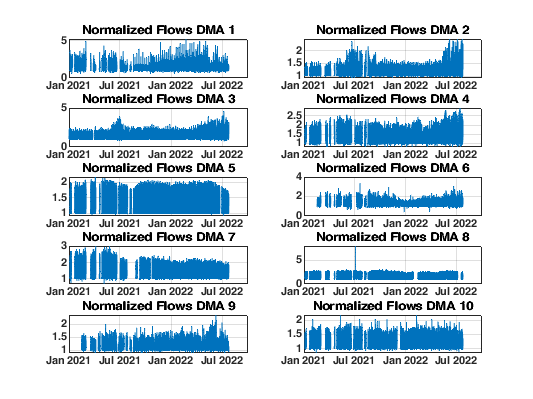

% Normalize DMA flows with movingMedianMNF
% Assuming 'uniqueDates' contains the dates for each day in the moving median MNF data
% Assuming 'TQ' contains the hourly timestamps for the DMA flows
% Assuming 'movingMedianMNF' contains the daily moving median MNF values

% Create an hourly time grid that spans the entire time range of TQ
hourlyTimeGrid = (min(TQ):hours(1):max(TQ))';

% Interpolate moving median MNF to hourly values
interpolatedMNF = zeros(length(hourlyTimeGrid), size(movingMedianMNF, 2));

for dmaIndex = 1:size(movingMedianMNF, 2)
    interpolatedMNF(:, dmaIndex) = interp1(uniqueDates, movingMedianMNF(:, dmaIndex), hourlyTimeGrid, 'linear', 'extrap');
end

% Assuming 'Q' contains the hourly DMA flow data
% Normalize the DMA flows

normalizedFlows = zeros(size(Q));

for dmaIndex = 1:size(Q, 2)
    % Matching the interpolated MNF with the flow data timestamps
    mnfForNormalization = interp1(hourlyTimeGrid, interpolatedMNF(:, dmaIndex), TQ, 'nearest');
    
    % Normalizing the flow data
    normalizedFlows(:, dmaIndex) = Q(:, dmaIndex) ./ mnfForNormalization;
end

figure;
for i = 1:10
    subplot(5,2,i);
    plot(TQ, normalizedFlows(:,i));  
    title(['Normalized Flows DMA ' num2str(i)]);
    grid on
end

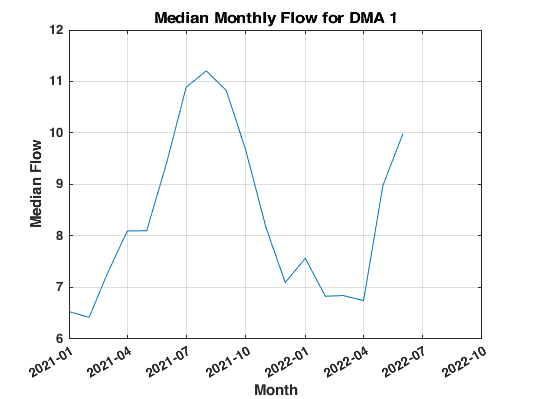

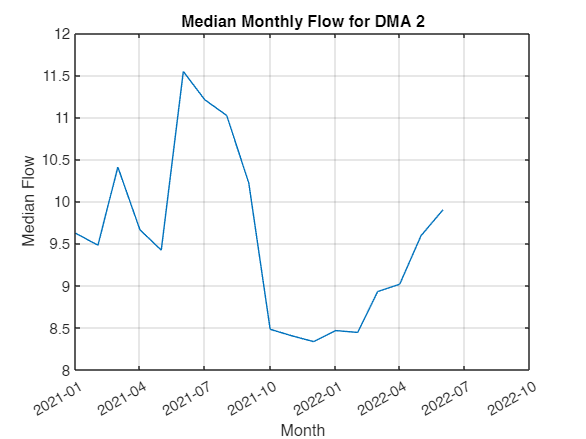

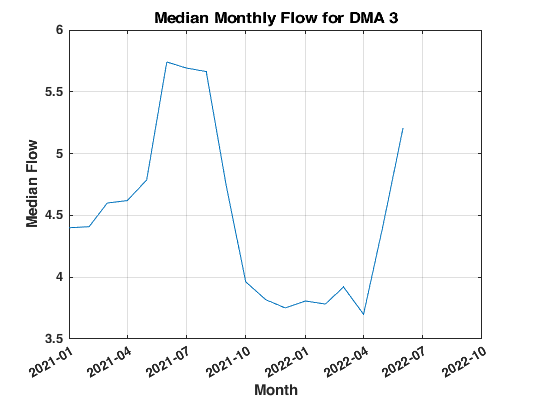

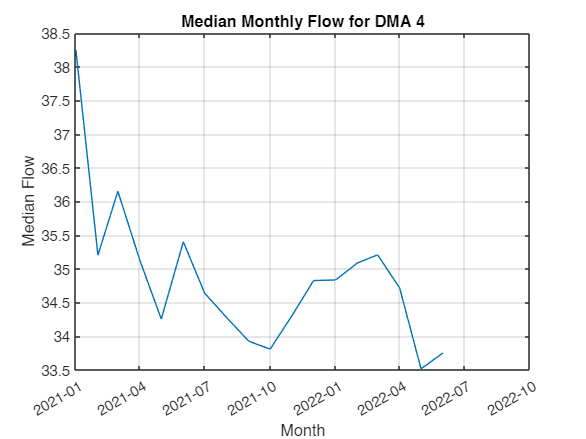

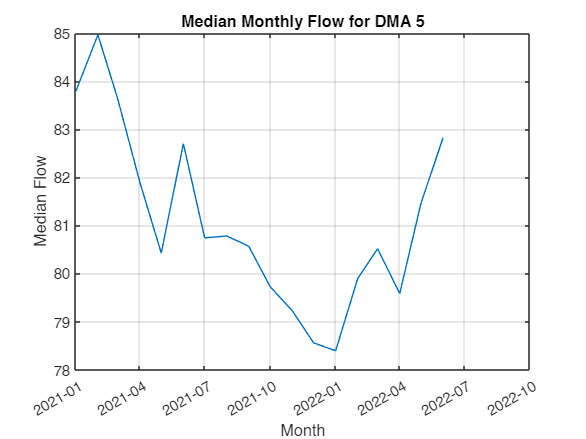

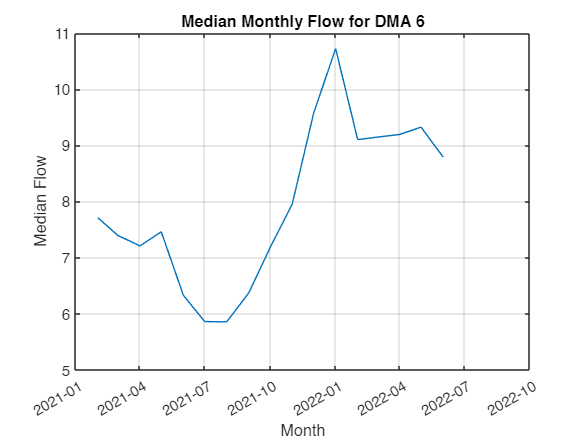

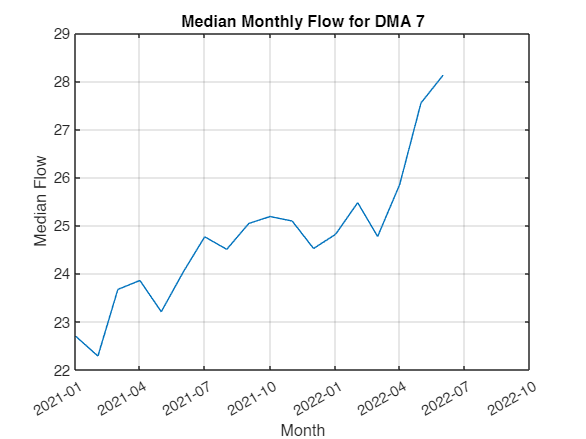

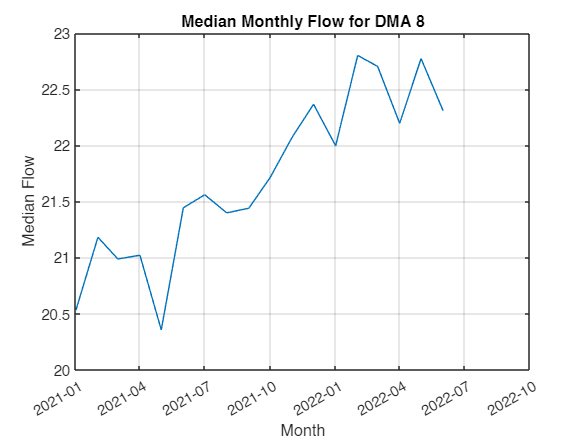

% Assuming TQ is your datetime array and Q is your flow data matrix

% Calculate the start and end dates for the entire dataset
startDate = dateshift(min(TQ), 'start', 'month');
endDate = dateshift(max(TQ), 'end', 'month');

% Create a list of the first day of each month in the range
monthList = startDate:calmonths(1):endDate;

% Number of months
numMonths = length(monthList) - 1;

% Initialize a cell array to hold flow data for each month
monthlyFlows = cell(numMonths, 1);

% Organize flows by month
for monthIdx = 1:numMonths
    % Find indices for the current month
    monthStart = monthList(monthIdx);
    monthEnd = monthList(monthIdx + 1);
    monthIndices = TQ >= monthStart & TQ < monthEnd;
    
    % Store flows for each month in the cell array
    monthlyFlows{monthIdx} = Q(monthIndices, :);
end

% Initialize a matrix to hold median monthly flows
medianMonthlyFlows = zeros(numMonths, size(Q, 2));

% Calculate median flows for each month
for monthIdx = 1:numMonths
    medianMonthlyFlows(monthIdx, :) = nanmedian(monthlyFlows{monthIdx}, 1); % Median along the first dimension
end

% Plot the median monthly flows for each DMA
for dmaIndex = 1:size(Q, 2)
    figure;
    plot(monthList(1:end-1), medianMonthlyFlows(:, dmaIndex)); % Exclude the last month if it's not complete
    title(['Median Monthly Flow for DMA ' num2str(dmaIndex)]);
    xlabel('Month');
    ylabel('Median Flow');
    datetick('x', 'yyyy-mm'); % Format the x-axis to show year and month
    grid on;
end

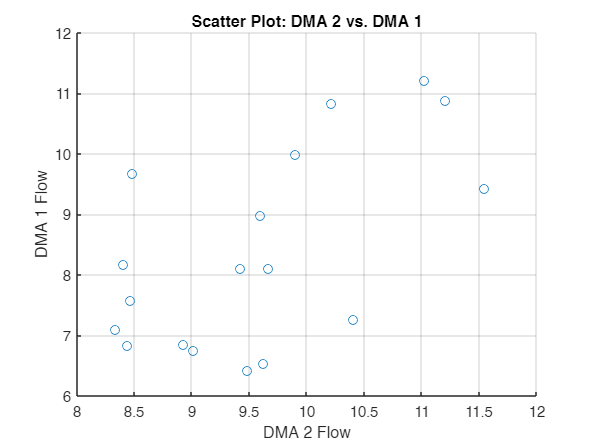

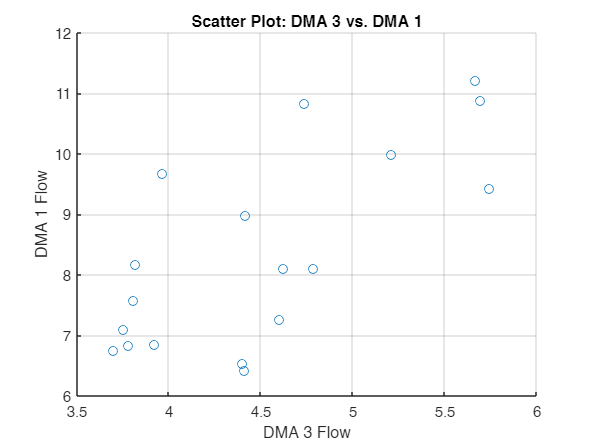

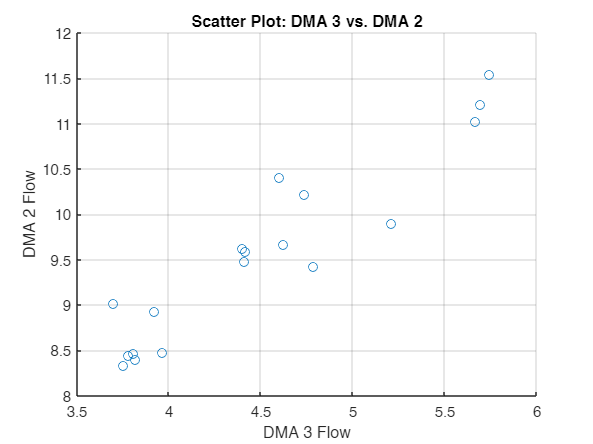

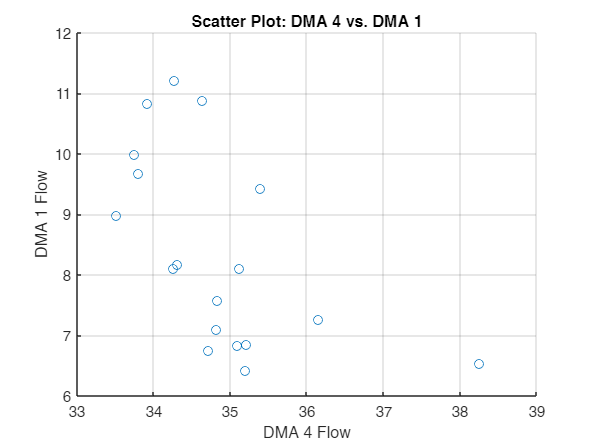

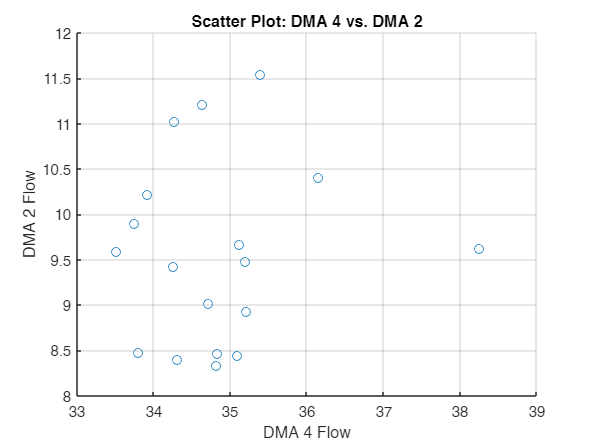

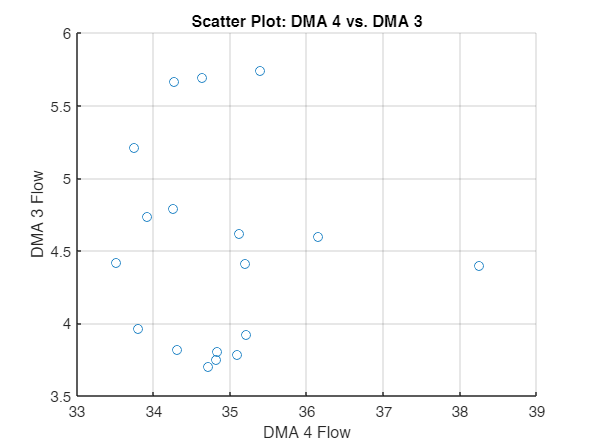

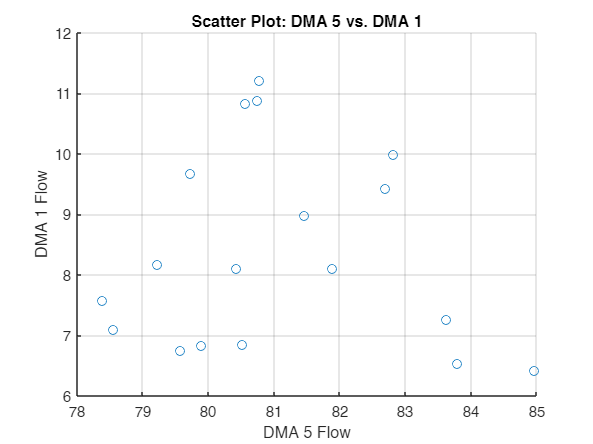

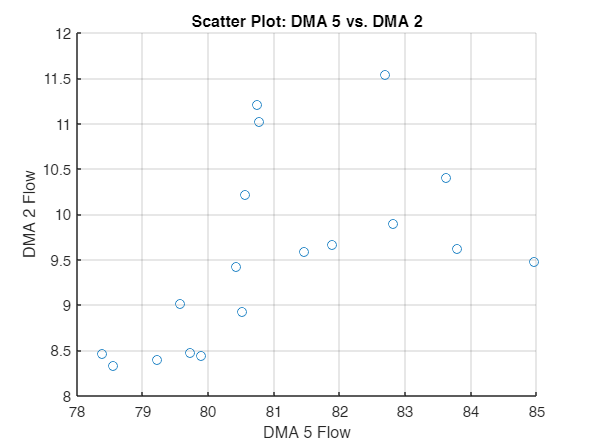

numDMAs = size(medianMonthlyFlows, 2);


% Loop through each pair of DMAs to create scatter plots with correlation lines
for i = 1:numDMAs
    for j = 1:i-1 % To avoid repeating pairs and comparing DMA with itself
        figure; % Create a new figure for each plot

        % Create scatter plot
        scatter(medianMonthlyFlows(:, i), medianMonthlyFlows(:, j));
        hold on; % Hold on to plot the correlation line

        % Fit a linear regression line
        p = polyfit(medianMonthlyFlows(:, i), medianMonthlyFlows(:, j), 1);
        xFit = linspace(min(medianMonthlyFlows(:, i)), max(medianMonthlyFlows(:, i)), 100);
        yFit = polyval(p, xFit);
        
        % Plot the linear regression line
        plot(xFit, yFit, 'r-', 'LineWidth', 1.5);

        % Enhance the plot
        title(['Scatter Plot with Correlation Line: DMA ' num2str(i) ' vs. DMA ' num2str(j)]);
        xlabel(['DMA ' num2str(i) ' Flow']);
        ylabel(['DMA ' num2str(j) ' Flow']);
        grid on;
        hold off; % Release the plot
    end
end
